## **Sound-Based Anomaly Detection using MIMII Audio Data**

## **Abstract**

해당 데이터셋은 용량이 매우 크기 때문에(100GB 이상) Preprocessing 및 Train / Test Data는 각 코드 블럭이 끝날 때 마다 해당 결과를 mat 형태로 저장하게 하였다. 그래서 학습 모델을 평가하는 부분 이외에는 코드를 모두 주석 처리하였다. 이는 Ctrl+T를 통해 해제한 후 코드를 실행할 수 있다.

## **Step 0~2: 데이터 인덱스 생성 과정**

**22000167 Kim inyeop**

Step 0

본 단계에서는 모든 데이터 처리를 위해 MATLAB 환경을 초기화 하고, 전체 WAV 파일의 경로와 메타정보를 저장할 인덱스 파일(wav_index_mat)의 이름을 정의한다. 이 인덱스는 추후 Train/Test 데이터 분할 및 라벨의 기준이 된다.

Step 1

산업 설비 음향 데이터셋은 dB(-6dB, 0dB, 6dB), 설비 종류(Fan, Pump, Slider, Valve), 상태(Normal, Abnormal, 정상=0, 비정상=1)을 가진다. 이 구조를 이용해 파일 기반 데이터셋을 체계적인 테이블 구조로 변환한다.

Step 2

탐색된 모든 WAV 파일 정보를 MATLAB의 테이블 형식으로 정리해 하나의 인덱스 테이블 T를 형성한다. 문자열, 수치형 데이터를 분리 및 저장함으로써 이후 데이터 로딩 및 분할 과정의 안정성을 확보한다. 마지막으로  wav_index_mat 파일 형태로 저장하여, 원본 오디오 데이터의 모델 학습 파이프라인을 분리하고 재사용 가능하게 한다.

% %% ============================================
% % 초기화
% %% ============================================
% close all; clear;

% 
% % Step 0: wav_index builder
% % Index를 생성해서 클래스를 추후 분할하는 것이 목표
% indexFile = "wav_index.mat";   % ←파일 이름 정의
% 
% %% ============================================
% %  STEP 1: 데이터셋 스캔 시작
% %% ============================================
% disp("🔍 wav_index.mat 파일 없음 → 데이터셋 스캔 시작...");

🔍 wav_index.mat 파일 없음 → 데이터셋 스캔 시작...


% rootPath = "../../Dataset/Sound";   % 최상위 Sound 폴더
% 
% % 리스트 변수 정의
% paths = {};
% db_domain_list = {};
% machine_list = {};
% id_list = {};
% state_list = {};
% label_list = [];
% 
% %% ============================================
% %  STEP 2-1 — 폴더 전체 스캔
% %% ============================================
% 
% % dB 단계 폴더 탐색
% level1 = dir(rootPath);
% level1 = level1([level1.isdir]);
% level1 = level1(~startsWith({level1.name}, '.'));
% 
% for i = 1:length(level1)
%     db_domain = level1(i).name;
%     db_path = fullfile(level1(i).folder, db_domain);
% 
%     level2 = dir(db_path);
%     level2 = level2([level2.isdir]);
%     level2 = level2(~startsWith({level2.name}, '.'));
% 
%     for j = 1:length(level2)
%         machine = level2(j).name;
%         machine_path = fullfile(level2(j).folder, machine);
% 
%         level3 = dir(machine_path);
%         level3 = level3([level3.isdir]);
%         level3 = level3(~startsWith({level3.name}, '.'));
% 
%         for k = 1:length(level3)
%             id_name = level3(k).name;
%             id_path = fullfile(level3(k).folder, id_name);
% 
%             level4 = dir(id_path);
%             level4 = level4([level4.isdir]);
%             level4 = level4(~startsWith({level4.name}, '.'));
% 
%             for m = 1:length(level4)
%                 state = level4(m).name;
%                 state_path = fullfile(level4(m).folder, state);
% 
%                 wavFiles = dir(fullfile(state_path, "*.wav"));
% 
%                 for n = 1:length(wavFiles)
%                     full_wav_path = fullfile(wavFiles(n).folder, wavFiles(n).name);
% 
%                     paths{end+1,1} = full_wav_path;
%                     db_domain_list{end+1,1} = db_domain;
%                     machine_list{end+1,1} = machine;
%                     id_list{end+1,1} = id_name;
%                     state_list{end+1,1} = state;
%                     label_list(end+1,1) = strcmp(state, "abnormal");
%                 end
%             end
%         end
%     end
% end
% 
% %% ============================================
% %  STEP 2-2 — 테이블 생성 + 저장
% %% ============================================
% 
% % 문자열 형태로 변환 (안정성을 위한 강제 변환)
% paths = string(paths);
% db_domain_list = string(db_domain_list);
% machine_list = string(machine_list);
% id_list = string(id_list);
% state_list = string(state_list);
% label_list = double(label_list);
% 
% T = table(paths, db_domain_list, machine_list, id_list, state_list, label_list, ...
%     'VariableNames', ["filepath","db_domain","machine","machine_id","state","label"]);
% 
% disp(T);

                                                             filepath                                                                db_domain       machine     machine_id      state       label
    ___________________________________________________________________________________________________________________________    ______________    ________    __________    __________    _____

    "C:\Users\user\OneDrive\2025-2\IAIA_Project1_2_PHM_Kiminyeop\Dataset\Sound\-6_dB_fan\fan\id_00\abnormal\00000000.wav"          "-6_dB_fan"       "fan"        "id_00"      "abnormal"      1  
    "C:\Users\user\OneDrive\2025-2\IAIA_Project1_2_PHM_Kiminyeop\Dataset\Sound\-6_dB_fan\fan\id_00\abnormal\00000001.wav"          "-6_dB_fan"       "fan"        "id_00"      "abnormal"      1  
    "C:\Users\user\OneDrive\2025-2\IAIA_Project1_2_PHM_Kiminyeop\Dataset\Sound\-6_dB_fan\fan\id_00\abnormal\00000002.wav"          "-6_dB_fan"       "fan"        "id_00"      "abnormal"      1  
    "C:\Users\user\OneDr

% fprintf("\n총 WAV 파일 개수: %d\n", height(T));


총 WAV 파일 개수: 54057


% 
% save(indexFile, "T");
% disp("💾 wav_index.mat 파일 저장 완료!");

## Step 3: log-Mel Spectrogram 생성

우선 wav_index.mat 파일을 불러와서 오디오 데이터에 대해 일관된 추출을 수행한다. log-Mel 파라미터 설정은 Step 3-1을 참조하면 되고, 이 파라미터를 통해 서로 다른 길이의 오디오 신호를 동일한 시간-주파수 해상도로 표현한다. 마지막으로 이렇게 표현한 데이터를 128x311 크기의 log-Mel 행렬 형태로 저장한다. 저장할 때는(WAV 파일 로드->스테레오 신호를 모노 신호로 변환->로그 스케일 적용->시간 프레임 길이 정규화->저장) 단계를 거친다.

% %% Step 3 — wav_index.mat 불러오기
% load("wav_index.mat", "T");   % T.filepath 사용 가능
% 
% %% Step 3-1 — log-Mel 생성 파라미터
% win = hann(1024, "periodic");
% hop = 512;
% numBands = 128;
% target_frames = 311;
% 
% %% Step 3-2 — 결과 저장 리스트
% logMel_all = cell(height(T), 1);
% 
% %% Step 3-3 — 전체 WAV 파일 체크
% for i = 1:height(T)
% 
%     % 1) 파일 경로
%     wavPath = T.filepath{i};  % ← 반드시 {} 로!
% 
%     % 2) WAV 읽기
%     [audio, fs] = audioread(wavPath);
% 
%     % 3) 스테레오이면 모노로 변환
%     if size(audio,2) > 1
%         audio = mean(audio, 2);
%     end
% 
%     % 4) log-Mel 생성
%     [A,~,~] = melSpectrogram(audio, fs, ...
%         'Window', win, ...
%         'OverlapLength', length(win) - hop, ...
%         'FFTLength', 1024, ...
%         'NumBands', numBands);
% 
%     logMel = log10(A + 1e-6);  % log scale
% 
%     % 5) 프레임 길이 맞추기 (padding / crop)
%     current_frames = size(logMel, 2);
% 
%     if current_frames < target_frames
%         % z-padding
%         logMel = padarray(logMel, [0, target_frames - current_frames], 'post');
%     elseif current_frames > target_frames
%         % crop
%         logMel = logMel(:, 1:target_frames);
%     end
% 
%     % 안전 검증
%     if size(logMel,1) ~= 128 || size(logMel,2) ~= target_frames
%         error("logMel size mismatch: %d × %d", size(logMel));
%     end
% 
%     % 6) 결과 저장
%     logMel_all{i} = logMel;
% 
%     % 상태 출력
%     if mod(i, 500) == 0
%         fprintf("Processed %d / %d\n", i, height(T));
%     end
% end

% %% Step 3-4 — 저장
% save("logMel_dataset.mat", "logMel_all", "-v7.3");
% disp("🔥 모든 log-Mel 생성 완료 & 저장됨!");

## Step 4: Sincnet Spectrogram 생성

우선 wav_index.mat 파일을 불러온 후 Step 4-1과 같은 파라미터를 설정한다. 그리고 Step 4-2에서 Sinc Filter Bank를 생성하는데 각 필터는 물리적으로 해석 가능한 주파수 대역을 가지며, 학습 가능한 필터를 사용하기 전 단계에서 고정된 형태의 Sinc 필터를 적용한다. 그리고 Step 4-3 실행 과정은 스테레오 신호를 모노 신호로 변환  -> FFT 기반 Convolution -> 각 필터 출력 신호에 대해 STFT 실행 -> 시간 프레임 고정 -> Sincnet Spectrogram 생성 단계를 거친다. 그리고 마지막으로 Step 4-4에서 결과가 저장된다.

% %% =======================================
% %  STEP 4 : SincNet-based Spectrograms (Full dataset, GPU Conv + CPU STFT)
% % =======================================
% 
% %% Step 4-1 - wav_index.mat 및 T 배열 불러오기
% load("wav_index.mat", "T");
% numFiles = height(T);
% 
% % === 전체 파일 처리 ===
% numTest = numFiles;
% 
% % === 파라미터 ===
% numFilters   = 40;
% filterLen    = 251;
% targetFrames = 311;
% fftLen       = 1024;
% hop          = 512;
% win          = hann(fftLen, "periodic");
% 
% % === sampling rate ===
% [~, fs] = audioread(T.filepath{1});
% 
% % === sinc filter bank ===
% filters = sincFilters(numFilters, filterLen, fs);   % [251 × 40]
% filters = single(filters);
% filtersGPU = gpuArray(filters);
% 
% % === Output cell ===
% sincSpec_all = cell(numTest, 1);
% 
% fprintf("🔥 Starting GPU-SincNet (FULL: %d files, GPU conv + CPU STFT)...\n", numTest);
% 
% %% =======================================
% %% 4-2 Sincnet 함수
% % =======================================
% for i = 1:numTest
% 
%     %% 1) Load audio
%     [audio, ~] = audioread(T.filepath{i});
%     if size(audio,2) > 1
%         audio = mean(audio,2);
%     end
%     audio = single(audio(:));
%     audioGPU = gpuArray(audio);
% 
%     N = length(audio);
% 
%     %% 2) FFT Size per-file (빠른 방식)
%     fftSize = 2^nextpow2(N + filterLen);
% 
%     %% 3) GPU FFT-based convolution
%     A = fft(audioGPU, fftSize);
% 
%     convGPU = zeros(numFilters, N, 'single', 'gpuArray');
% 
%     for f = 1:numFilters
%         Ff = fft(filtersGPU(:,f), fftSize);
%         Y = ifft(A .* Ff, fftSize, 'symmetric');
%         convGPU(f,:) = Y(1:N);
%     end
% 
%     %% 4) CPU 가져오기 (STFT CPU → 출력 즉시 됨)
%     convCPU = gather(convGPU);
% 
%     %% 5) STFT per filter
%     sincSpec = zeros(numFilters, targetFrames, 'single');
% 
%     for f = 1:numFilters
%         sig = convCPU(f,:);
% 
%         S = stft(sig, fs, ...
%             'Window', win, ...
%             'OverlapLength', length(win)-hop, ...
%             'FFTLength', fftLen);
% 
%         mag = abs(S);
%         cf = size(mag,2);
% 
%         % normalize to fixed frames
%         if cf < targetFrames
%             mag = padarray(mag, [0 targetFrames-cf], 'post');
%         else
%             mag = mag(:,1:targetFrames);
%         end
% 
%         sincSpec(f,:) = mean(mag,1);
%     end
% 
%     sincSpec_all{i} = sincSpec;
% 
%     %% 6) 실시간 진행률 출력
%     if mod(i,50) == 0 || i == 1
%         fprintf("✔ %d / %d (%.2f%%)\n", i, numTest, i/numTest*100);
%     end
% end
% 
% %% =======================================
% %% 4-3 SAVE
% % =======================================
% save("sincSpec_full_GPU_CPU_STFT.mat", "sincSpec_all", "-v7.3");
% fprintf("✅ Saved: sincSpec_full_GPU_CPU_STFT.mat\n");

## Step 5: lMS Spectrogram 생성

먼저 Step 5-1에서 wav_index.mat, logMel_dataset.mat(log-Mel Spectrogram), sincSpec_full_GPU_CPU_STFT.mat(Sincnet Spectrogram)을 불러온다. log-Mel과 Sincnet은 동일한 WAV 파일 순서를 기준으로 정렬되고, 이 두 특징을 결합하여 하나의 입력인 lMS Spectrogram을 생성한다. Step 5-2에서 채널 결합 방법이 설명되어 있는데, 먼저 log-Mel을 첫 번째 채널로, Sincnet Spectrogram을 두 번째 채널로 사용해서 최종 입력 크기 128x311x2 형태인 lMS Spectrogram을 형성한다. 그리고 마지막으로 Step 5-3에서 lMS Spectrogram 데이터를 저장한다.

% %% ================================================
% % STEP 5 — lMS Feature Fusion (log-Mel + SincNet)
% % ================================================
% 
% % Step 5-1 Load indexed table + features
% load("wav_index.mat", "T");
% load("logMel_dataset.mat", "logMel_all");
% load("sincSpec_full_GPU_CPU_STFT.mat", "sincSpec_all");   % [40×311]
% 
% N = numel(logMel_all);
% 
% % Final target size
% H = 128;
% W = 311;
% 
% % Pre-allocate final feature array
% lMS_all = zeros(H, W, 2, N, "single");
% 
% fprintf("🔥 Starting lMS fusion (%d samples)...\n", N);
% %% =======================================
% %% 5-2 lMS-Spectogram
% % =======================================
% for i = 1:N
% 
%     mel = single(logMel_all{i});           % 128×311
%     sinc = single(sincSpec_all{i});        % 40×311
% 
%     % resize SincSpec to 128×311
%     sinc_resized = imresize(sinc, [H W]);
% 
%     % channel 1 = logMel
%     % channel 2 = sincSpec resized
%     lMS_all(:,:,1,i) = mel;
%     lMS_all(:,:,2,i) = sinc_resized;
% 
%     if mod(i, 100) == 0
%         fprintf("Processed %d / %d (%.1f%%)\n", i, N, i/N*100);
%     end
% end
% 
% fprintf("🔥 Fusion complete.\n");
% 
% % 5-3 Save
% save("lMS_dataset.mat", "lMS_all", "-v7.3");
% fprintf("💾 Saved: lMS_dataset.mat\n");

## Step 6: lMS 데이터셋 그룹화(12개 클래스 생성

Step 6-1에서는 wav_index.mat과 lMS_dataset.mat을 불러와서 메타 정보(machine, dB), 특징 데이터(lMS)를 연결한다. Step 6-2에서는 이제 총 12개의 클래스를 분할하는 과정인데 분할 기준은 Machine(Fan, Pump, Slider, Valve), dB level(-6dB, 0dB, 6dB)이다. 이렇게 데이터셋을 분할해서 Step 6-3에서 splitDataset.mat 형태로 저장한다. 이 데이터는 추후 Train/Test 및 모델 학습에 사용된다.

% %% ======================================================
% %   STEP 6: 12개 그룹 생성 (fan/pump/slider/valve × -6/0/6)
% %   실행 후 → splitDataset.mat 자동 저장
% %% ======================================================
% 
% %% Step 6-1: 데이터셋 불러오기
% load("wav_index.mat","T");
% load("lMS_dataset.mat","lMS_all");
% 
% %% Step 6-2: Feature Group Extraction
% % dB 값만 추출 (-6 / 0 / 6)
% T.db_value = extractBefore(T.db_domain, "_dB");
% 
% machines  = ["fan","pump","slider","valve"];
% db_values = ["-6","0","6"];
% 
% % 저장할 변수 임시 리스트
% savedVars = {};
% 
% for m = machines
%     for d = db_values
% 
%         % Boolean index
%         idx = strcmp(T.machine, m) & strcmp(T.db_value, d);
% 
%         % dB 태그 생성
%         if d == "-6"
%             dtag = "dbm6";
%         elseif d == "0"
%             dtag = "db0";
%         elseif d == "6"
%             dtag = "dbp6";
%         end
% 
%         % 변수 이름
%         varX = sprintf("X_%s_%s", m, dtag);
%         varY = sprintf("Y_%s_%s", m, dtag);
% 
%         % 실제 데이터 추출
%         X = lMS_all(:,:,:, idx);
%         Y = T.label(idx);
% 
%         % Workspace에 저장
%         assignin("base", varX, X);
%         assignin("base", varY, Y);
% 
%         % 저장 목록 추가
%         savedVars = [savedVars, {varX, varY}];
% 
%         fprintf("생성됨 → %s (%d개)\n", varX, size(X,4));
%     end
% end
% 
% %% ======================================================
% %   Step 6-3: 모든 그룹 저장 → splitDataset.mat
% %% ======================================================
% 
% save("splitDataset.mat", savedVars{:}, "-v7.3");
% 
% disp("💾 Saved splitDataset.mat (12개 그룹 + 라벨)");

## Step 7: Train/Test Split

Step 7-1에서 12개 조건으로 분리된 데이터셋 splitDataset.mat 파일을 불러온다. 그리고 Step 7-2에서 각각 정상과 비정상 클래스 비율을 유지한 상태로 Train:Test=8:2 비율로 분할한다. 이를 통해 데이터 불균형에 의한 학습 편향을 방지하고, 모든 조건에서 성능을 공정하게 비교할 수 있도록 한다. 분할 과정은 7-3에서 더 자세히 나와있는데, 정상(0), 비정상(1) 샘플 인덱스를 분리해서 클래스 별로 무작위 셔플을 돌린다. 그리고 각 클래스에서 80%를 학습 데이터로 선택하고 20%를 테스트 데이터로 사용한다. 그리고 마지막으로 Train / Test 인덱스를 다시 셔플하여 순서 편향을 제거하였다. 그리고 이렇게 Train / Test가 진행된 결과를 trainTestData.mat에 저장하였다. 학습 함수는 train_12models.m 기반으로 실행하였다.

%% ======================================================
%  STEP 7: Stratified Train/Test Split
%  - 정상 / 비정상 각각 8:2 유지
%  - 12개 데이터셋 모두 동일 기준
%  - 결과: trainTestData.mat
%% ======================================================

%% ------------------------------------------------------
% Step 7-1 Load split dataset
%% ------------------------------------------------------
load("splitDataset.mat");    % X_*, Y_* 로드됨
fprintf("Loaded splitDataset.mat\n");

Loaded splitDataset.mat


% 
% %% ------------------------------------------------------
% % Dataset list
% %% ------------------------------------------------------
% datasets = {
%     "fan_dbm6", "fan_db0", "fan_dbp6", ...
%     "pump_dbm6", "pump_db0", "pump_dbp6", ...
%     "slider_dbm6", "slider_db0", "slider_dbp6", ...
%     "valve_dbm6", "valve_db0", "valve_dbp6"
% };
% 
% %% Step 7-2 Train/Test 분할
% ratio = 0.8;   % 80% Train / 20% Test
% 
% trainData = struct();
% testData  = struct();
% 
% %% ------------------------------------------------------
% % Step 7-3: Train / Test 분할 함수
% %% ------------------------------------------------------
% for i = 1:length(datasets)
% 
%     ds = datasets{i};
% 
%     % --- Load dataset
%     X = eval(sprintf("X_%s", ds));   % [128×311×2×N]
%     Y = eval(sprintf("Y_%s", ds));   % [N×1] (0=normal, 1=abnormal)
% 
%     % --- Split indices by class
%     idx_normal   = find(Y == 0);
%     idx_abnormal = find(Y == 1);
% 
%     % Shuffle within each class
%     idx_normal   = idx_normal(randperm(numel(idx_normal)));
%     idx_abnormal = idx_abnormal(randperm(numel(idx_abnormal)));
% 
%     % Number of samples per class
%     Nn_tr = floor(numel(idx_normal)   * ratio);
%     Na_tr = floor(numel(idx_abnormal) * ratio);
% 
%     % Train / Test indices
%     trainIdx = [
%         idx_normal(1:Nn_tr);
%         idx_abnormal(1:Na_tr)
%     ];
% 
%     testIdx = [
%         idx_normal(Nn_tr+1:end);
%         idx_abnormal(Na_tr+1:end)
%     ];
% 
%     % Shuffle again (remove ordering bias)
%     trainIdx = trainIdx(randperm(numel(trainIdx)));
%     testIdx  = testIdx(randperm(numel(testIdx)));
% 
%     trainData.(ds).X = X(:,:,:,trainIdx);
%     trainData.(ds).Y = Y(trainIdx);
% 
%     testData.(ds).X  = X(:,:,:,testIdx);
%     testData.(ds).Y  = Y(testIdx);
% 
%     % --- Print ratio check
%     fprintf("%s\n", ds);
%     fprintf("  Train: %4d (normal=%4d, abnormal=%4d)\n", ...
%         numel(trainIdx), sum(Y(trainIdx)==0), sum(Y(trainIdx)==1));
%     fprintf("  Test : %4d (normal=%4d, abnormal=%4d)\n\n", ...
%         numel(testIdx),  sum(Y(testIdx)==0),  sum(Y(testIdx)==1));
% end

fan_dbm6


  Train: 4440 (normal=3260, abnormal=1180)


  Test : 1110 (normal= 815, abnormal= 295)



fan_db0


  Train: 4440 (normal=3260, abnormal=1180)


  Test : 1110 (normal= 815, abnormal= 295)



fan_dbp6


  Train: 4440 (normal=3260, abnormal=1180)


  Test : 1110 (normal= 815, abnormal= 295)



pump_dbm6


  Train: 3363 (normal=2999, abnormal= 364)


  Test :  842 (normal= 750, abnormal=  92)



pump_db0


  Train: 3363 (normal=2999, abnormal= 364)


  Test :  842 (normal= 750, abnormal=  92)



pump_dbp6


  Train: 3363 (normal=2999, abnormal= 364)


  Test :  842 (normal= 750, abnormal=  92)



slider_dbm6


  Train: 3275 (normal=2563, abnormal= 712)


  Test :  819 (normal= 641, abnormal= 178)



slider_db0


  Train: 3275 (normal=2563, abnormal= 712)


  Test :  819 (normal= 641, abnormal= 178)



slider_dbp6


  Train: 3275 (normal=2563, abnormal= 712)


  Test :  819 (normal= 641, abnormal= 178)



valve_dbm6


  Train: 3335 (normal=2952, abnormal= 383)


  Test :  835 (normal= 739, abnormal=  96)



valve_db0


  Train: 3335 (normal=2952, abnormal= 383)


  Test :  835 (normal= 739, abnormal=  96)



valve_dbp6


  Train: 3335 (normal=2952, abnormal= 383)


  Test :  835 (normal= 739, abnormal=  96)



% 
% %% ------------------------------------------------------
% % Step 7-5: Save Dataset
% %% ------------------------------------------------------
% save("trainTestData.mat", "trainData", "testData", "-v7.3");
% disp("✅ Saved trainTestData.mat (Stratified 8:2 split)");

✅ Saved trainTestData.mat (Stratified 8:2 split)


## Step 8: CNN 모델 성능 평가

Step 8-1에서는 Step 7에서 생성한 (trainTestData.mat) 중 testData(테스트 데이터)만을 불러온다. 모델 학습에 사용되지 않은 데이터만으로 성능을 평가함으로써 과적합 문제를 방지한다. Step 8-2에서는 조건별 모델을 평가하는데 총 12개의 평가 결과가 있으며, 각 모델마다는 Confusion Matrix, ROC Curve 및 AUC 평가 모델이 있다.

%% ====================================================
%   Step 8: 12개 모델 Confusion Matrix + ROC/AUC 자동 플롯
%% ====================================================

%% Step 8-1: Train / Test 데이터 불러오기
load("trainTestData.mat", "testData");

datasets = {
    "fan_dbm6", "fan_db0", "fan_dbp6", ...
    "pump_dbm6", "pump_db0", "pump_dbp6", ...
    "slider_dbm6", "slider_db0", "slider_dbp6", ...
    "valve_dbm6", "valve_db0", "valve_dbp6"
};


📌 Plotting: fan_dbm6


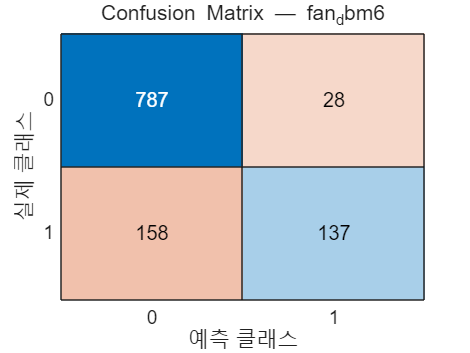

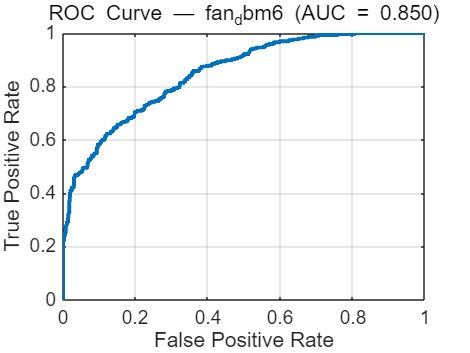


📌 Plotting: fan_db0


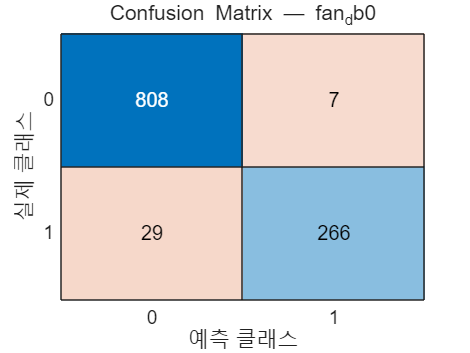

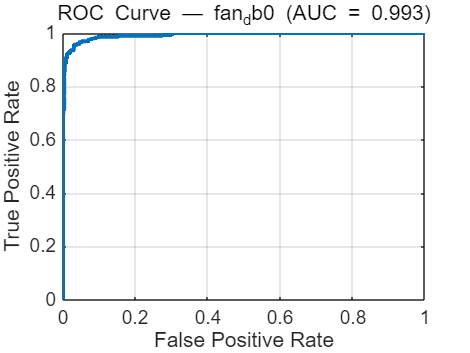


📌 Plotting: fan_dbp6


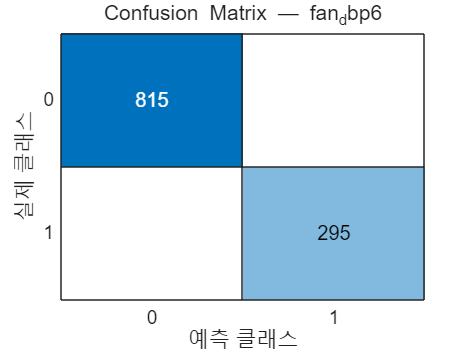

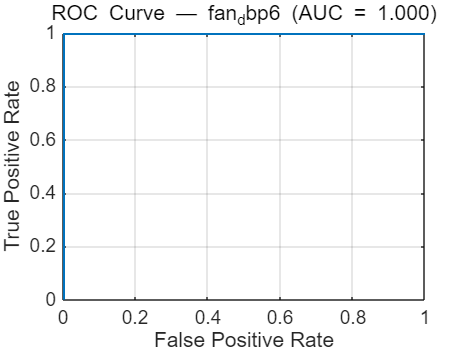


📌 Plotting: pump_dbm6


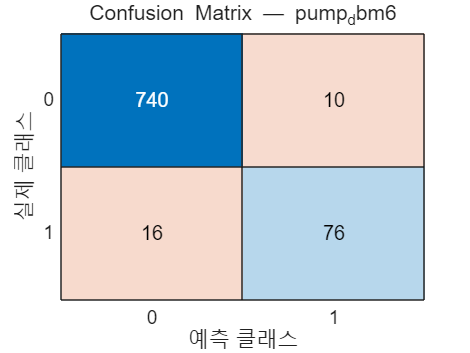

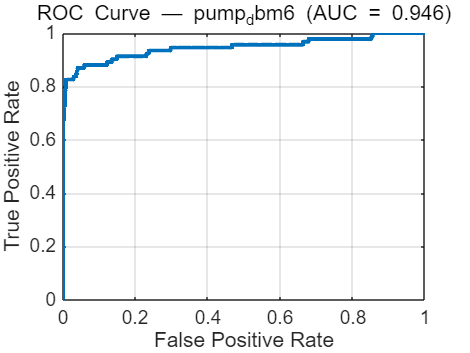


📌 Plotting: pump_db0


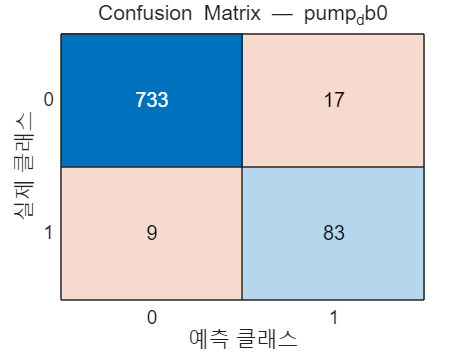

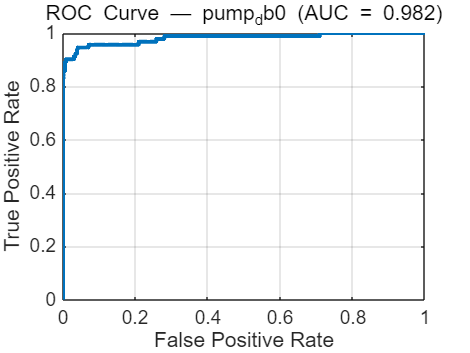


📌 Plotting: pump_dbp6


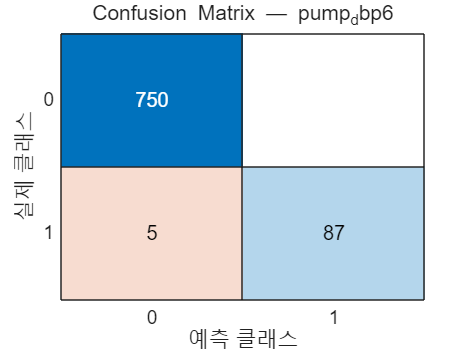

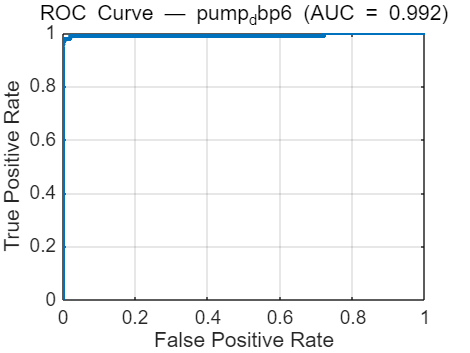


📌 Plotting: slider_dbm6


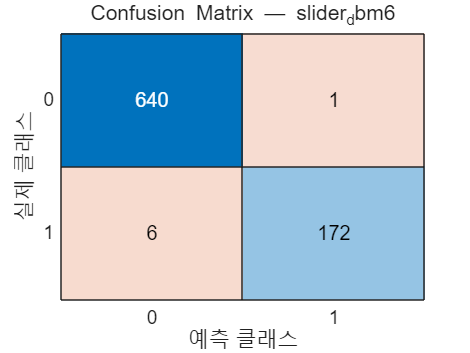

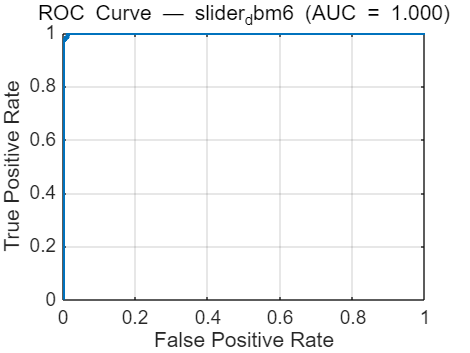


📌 Plotting: slider_db0


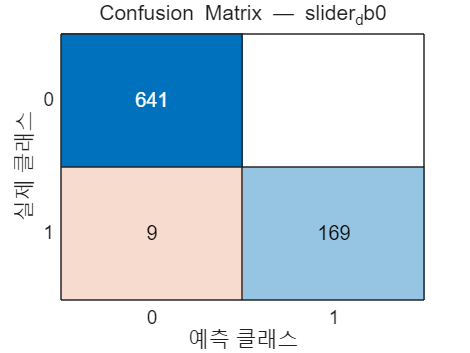

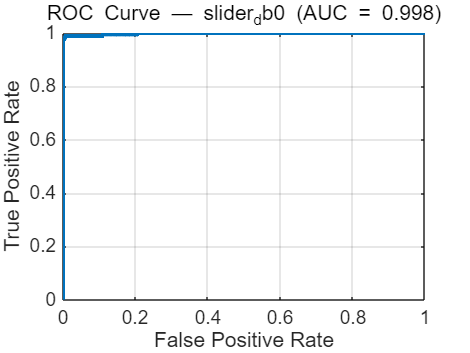


📌 Plotting: slider_dbp6


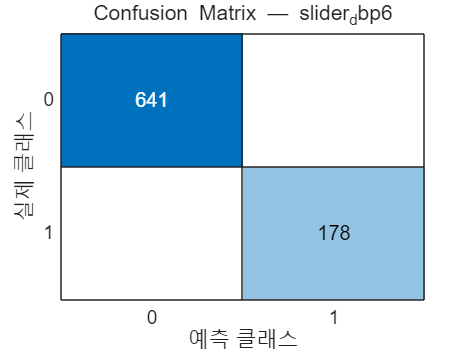

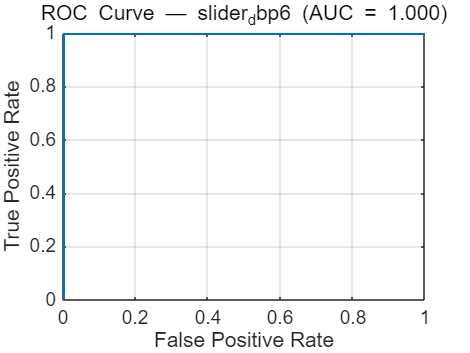


📌 Plotting: valve_dbm6


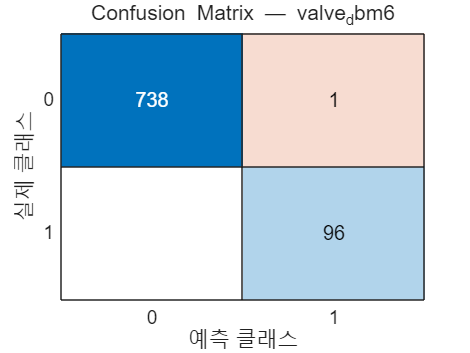

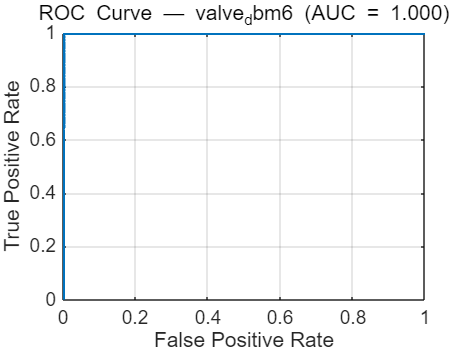


📌 Plotting: valve_db0


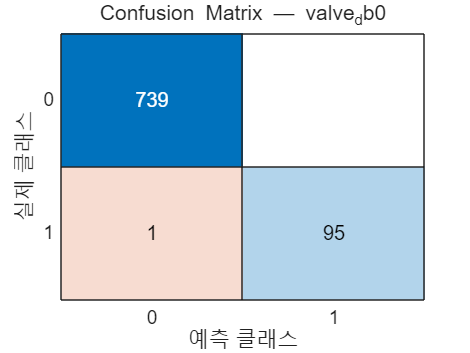

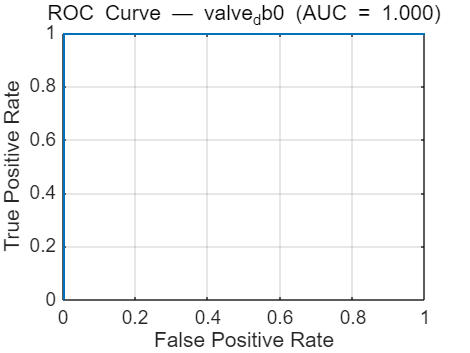


📌 Plotting: valve_dbp6


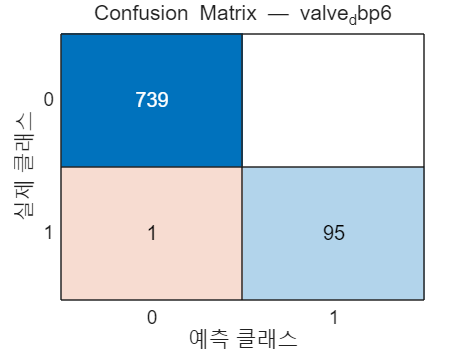

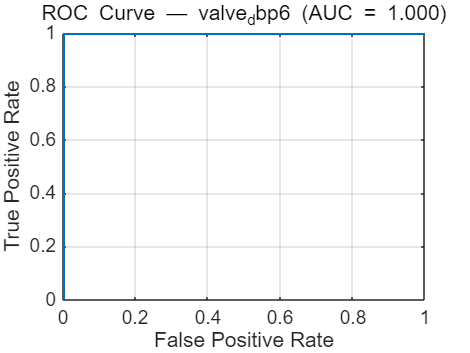

%% Step 8-2: Confusion Matrix 함수
for i = 1:length(datasets)

    modelName = datasets{i};
    fprintf("\n📌 Plotting: %s\n", modelName);

    % Load model
    S = load(sprintf("net_%s.mat", modelName));
    net = S.net;

    % Load test data
    Xtest = testData.(modelName).X;
    Ytest = categorical(testData.(modelName).Y);

    %% ---------- Confusion Matrix ----------
    YPred = classify(net, Xtest);

    figure;
    confusionchart(Ytest, YPred);
    title("Confusion Matrix — " + modelName);

    %% ---------- ROC / AUC ----------
    scores = predict(net, Xtest);  % Softmax 출력
    [Xroc, Yroc, ~, AUC] = perfcurve(Ytest, scores(:,2), '1');

    figure;
    plot(Xroc, Yroc, 'LineWidth', 2);
    grid on;
    xlabel("False Positive Rate");
    ylabel("True Positive Rate");
    title(sprintf("ROC Curve — %s (AUC = %.3f)", modelName, AUC));

end

## **Step 9: CNN 분류 성능 지표 계산**

해당 단계에서는 이전 단계에서 실행한 분류 성능을 정량적으로 평가한다. 평가 기준은 Accuracy(전체 샘플 중 올바르게 분류된 비율), Precision(비정상으로 분류된 새믈 중 실제 비정상 비율), Recall(실제 비정상 중 올바르게 검출한 비율), F1-Score(Precision과 Recall의 조화 평균) 네 가지 항목이다.

%% Step 9: Accuracy, precision, Recall, F1-Score 계산
datasets = {
    "fan_dbm6", "fan_db0", "fan_dbp6", ...
    "pump_dbm6", "pump_db0", "pump_dbp6", ...
    "slider_dbm6", "slider_db0", "slider_dbp6", ...
    "valve_dbm6", "valve_db0", "valve_dbp6"
};

fprintf("\n=== Classification Metrics (Accuracy / Precision / Recall / F1) ===\n\n");


=== Classification Metrics (Accuracy / Precision / Recall / F1) ===



%% Step 9-1: Accuracy, precision, Recall, F1-Score 계산 함수
for i = 1:length(datasets)

    modelName = datasets{i};

    % Load model
    S = load(sprintf("net_%s.mat", modelName));
    net = S.net;

    % Load test data
    Xtest = testData.(modelName).X;
    Ytrue = testData.(modelName).Y;   % 0(normal) / 1(abnormal)

    % Prediction
    Ypred = classify(net, Xtest);
    Ypred = double(Ypred == categorical(1));   % categorical → 0/1

    % Confusion matrix elements
    TP = sum((Ypred == 1) & (Ytrue == 1));
    TN = sum((Ypred == 0) & (Ytrue == 0));
    FP = sum((Ypred == 1) & (Ytrue == 0));
    FN = sum((Ypred == 0) & (Ytrue == 1));

    % Metrics
    accuracy  = (TP + TN) / (TP + TN + FP + FN);
    precision = TP / (TP + FP + eps);
    recall    = TP / (TP + FN + eps);
    f1        = 2 * precision * recall / (precision + recall + eps);

    % Print
    fprintf("[%s]\n", modelName);
    fprintf("  Accuracy : %.4f\n", accuracy);
    fprintf("  Precision: %.4f\n", precision);
    fprintf("  Recall   : %.4f\n", recall);
    fprintf("  F1-score : %.4f\n\n", f1);

end

[fan_dbm6]


  Accuracy : 0.8324


  Precision: 0.8303


  Recall   : 0.4644


  F1-score : 0.5957



[fan_db0]


  Accuracy : 0.9676


  Precision: 0.9744


  Recall   : 0.9017


  F1-score : 0.9366



[fan_dbp6]


  Accuracy : 1.0000


  Precision: 1.0000


  Recall   : 1.0000


  F1-score : 1.0000



[pump_dbm6]


  Accuracy : 0.9691


  Precision: 0.8837


  Recall   : 0.8261


  F1-score : 0.8539



[pump_db0]


  Accuracy : 0.9691


  Precision: 0.8300


  Recall   : 0.9022


  F1-score : 0.8646



[pump_dbp6]


  Accuracy : 0.9941


  Precision: 1.0000


  Recall   : 0.9457


  F1-score : 0.9721



[slider_dbm6]


  Accuracy : 0.9915


  Precision: 0.9942


  Recall   : 0.9663


  F1-score : 0.9801



[slider_db0]


  Accuracy : 0.9890


  Precision: 1.0000


  Recall   : 0.9494


  F1-score : 0.9741



[slider_dbp6]


  Accuracy : 1.0000


  Precision: 1.0000


  Recall   : 1.0000


  F1-score : 1.0000



[valve_dbm6]


  Accuracy : 0.9988


  Precision: 0.9897


  Recall   : 1.0000


  F1-score : 0.9948



[valve_db0]


  Accuracy : 0.9988


  Precision: 1.0000


  Recall   : 0.9896


  F1-score : 0.9948



[valve_dbp6]


  Accuracy : 0.9988


  Precision: 1.0000


  Recall   : 0.9896


  F1-score : 0.9948



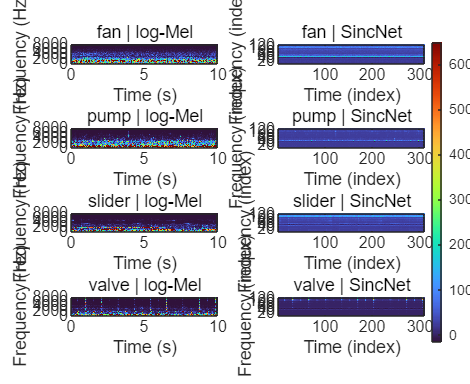

%% 외전: log-Mel, Sincnet 플롯
machines = {'fan','pump','slider','valve'};
fname = "trainTestData.mat";

fs    = 16000;
T_sec = 10;
fmax  = 8000;

figure('Color','w','Position',[100 100 1100 900]);
plot_idx = 1;

for i = 1:numel(machines)

    ds = sprintf('%s_dbp6', machines{i});

    % --- log-Mel (채널 1) 샘플 1개만 읽기
    X_logmel = h5read(fname, ...
        "/trainData/" + ds + "/X", ...
        [1 1 1 1], [128 311 1 1]);
    X_logmel = squeeze(X_logmel);

    % --- SincNet (채널 2) 샘플 1개만 읽기
    X_sinc = h5read(fname, ...
        "/trainData/" + ds + "/X", ...
        [1 1 2 1], [128 311 1 1]);
    X_sinc = squeeze(X_sinc);

    [F,T] = size(X_logmel);
    time_axis = linspace(0, T_sec, T);
    freq_axis = linspace(0, fmax, F);

    % -------- log-Mel --------
    subplot(4,2,plot_idx)
    clow  = prctile(X_logmel(:), 5);
    chigh = prctile(X_logmel(:), 95);
    imagesc(time_axis, freq_axis, X_logmel);
    axis xy tight
    caxis([clow chigh])
    title(sprintf('%s | log-Mel', machines{i}))
    xlabel('Time (s)'); ylabel('Frequency (Hz)')
    plot_idx = plot_idx + 1;

    % -------- SincNet --------
    subplot(4,2,plot_idx)
    imagesc(X_sinc);
    axis xy tight
    title(sprintf('%s | SincNet', machines{i}))
    xlabel('Time (index)'); ylabel('Frequency (index)')
    plot_idx = plot_idx + 1;
end

colormap turbo
colorbar('Position',[0.92 0.11 0.02 0.78]);

## Step 10: CNN 출력 점수 분포 시각화

12개 모델의 평가 성능을 시행한 결과, -6dB Fan에서는 Recall 점수가 저조하게 나왔다. 그렇기 때문에 모델이 정상과 비정상을 출력 확률 분포 차이로 잘 구별하고 있는지 플롯한 후 문제점을 파악한다. 그래서 CNN 정량 지표만으로는 확인하기 어려운 모델의 Margin과 분리 정도를 히스토그램으로 시각화하였다. 정상 비정상 판별이 잘 되지 않았던 -6dB Fan과, 잘 판별되었던 6dB Fan 두 개를 가져와서 히스토그램 상에 어떤 차이가 있는지를 살펴본다. 정상 샘플은 낮은 Abnormal Score에 있으면 이상적, 비정상 샘플은 높은 Abnormal Score에 있으면 이상적인데, 정상은 왼쪽, 비정상은 오른쪽에 분포되어 있는 6dB Fan과 달리 -6dB Fan은 정상과 비정상 모두 혼합되어 있는 모습을 보인다. 이는 곧 -6dB Fan의 낮은 모델 분류 성능을 설명하는 근거가 된다.

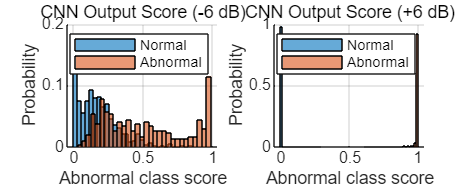

%% Step 10: -6dB Fan Normal/Abnormal 잘 구분되는지 플롯
cases = {
    'fan_dbm6', 'net_fan_dbm6.mat', '-6 dB';
    'fan_dbp6', 'net_fan_dbp6.mat', '+6 dB'
};

figure('Color','w','Position',[100 100 1000 400]);

for i = 1:2
    ds = cases{i,1};
    net = load(cases{i,2}).net;
    label = cases{i,3};

    Xtest = testData.(ds).X;
    Ytest = testData.(ds).Y;

    scores = predict(net, Xtest);
    s_abn = scores(:,2);   % abnormal score

    subplot(1,2,i); hold on;

    histogram(s_abn(Ytest==0), 30, ...
        'Normalization','probability', 'FaceAlpha',0.6);
    histogram(s_abn(Ytest==1), 30, ...
        'Normalization','probability', 'FaceAlpha',0.6);

    xlabel('Abnormal class score');
    ylabel('Probability');
    title(sprintf('CNN Output Score (%s)', label));
    legend('Normal','Abnormal');
    grid on;
end

## Step 11: CNN-LSTM 모델 학습 및 평가

Step 10에서 -6dB Fan의 문제점을 확인하였다. 그래서 본 단계에서는 CNN-LSTM 모델에 적합하게 하기 위해 2D Spectrogram을 시계열(Sequence) 형태롤 변환한다. 입력 파라미터는 Step 11-1 하단 부분을 참조하면 된다. Adam 옵티마이저를 사용하여 학습하였고, Confusion Matrix를 통해 정상 / 비정상 분류 성능을 정량적으로 평가한다.

%% Step 11. TrainTestData 다시 호출 후 CNN-LSTM 학습 시작
load("trainTestData.mat")
X_train = trainData.fan_dbm6.X;   % [128×311×2×Ntrain]
Y_train = trainData.fan_dbm6.Y;   % 0(normal), 1(abnormal)

X_test  = testData.fan_dbm6.X;
Y_test  = testData.fan_dbm6.Y;

fprintf("Train: %d, Test: %d\n", size(X_train,4), size(X_test,4));

Train: 4440, Test: 1110


%% Step 11-1: CNN-LSTM 학습 시작
Ntr = size(X_train,4);
Nte = size(X_test,4);

% === sequence로 변환: [128×311×2] -> [256×311]
Xseq_train = cell(Ntr,1);
for i = 1:Ntr
    tmp = permute(X_train(:,:,:,i), [1 3 2]);  % [128×2×311]
    Xseq_train{i} = reshape(tmp, [], size(tmp,3)); % [256×311]
end

Xseq_test = cell(Nte,1);
for i = 1:Nte
    tmp = permute(X_test(:,:,:,i), [1 3 2]);
    Xseq_test{i} = reshape(tmp, [], size(tmp,3));
end

Yseq_train = categorical(Y_train);
Yseq_test  = categorical(Y_test);

% === 길이 체크
lens = cellfun(@(x) size(x,2), Xseq_train);
fprintf("Train sequence length: Min=%d, Max=%d\n", min(lens), max(lens));

Train sequence length: Min=311, Max=311


단일 GPU에서 훈련합니다.
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　Ｅｐｏｃｈ　　｜　　반복　횟수　　｜　　　　경과　시간　　　　　｜　　미니　배치　정확도　　｜　　미니　배치　손실　　｜　　기본　학습률　　｜
｜　　　　　　　　　｜　　　　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　｜　　　　　　　　　　　　｜　　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　　１　｜　　　　　　　１　｜　　　　　００：００：０３　｜　　　　　　７５．００％　｜　　　　　０．６２２３　｜　　　０．００１０　｜
｜　　　　　　　１　｜　　　　　　５０　｜　　　　　００：００：０６　｜　　　　　　７１．８８％　｜　　　　　０．５８４０　｜　　　０．００１０　｜
｜　　　　　　　１　｜　　　　　１００　｜　　　　　００：００：０９　｜　　　　　　７１．８８％　｜　　　　　０．６３７０　｜　　　０．００１０　｜
｜　　　　　　　２　｜　　　　　１５０　｜　　　　　００：００：１１　｜　　　　　　６５．６２％　｜　　　　　０．６８２４　｜　　　０．００１０　｜
｜　　　　　　　２　｜　　　　　２００　｜　　　　　００：００：１４　｜　　　　　　７５．００％　｜　　　　　０．５８２８　｜　　　０．００１０　｜
｜　　　　　　　２　｜　　　　　２５０　｜　　　　　００：００：１７　｜　　　　　　６８．７５％　｜　　　　　０．６６９３　｜　　　０．００１０　｜
｜　　　　　　　３　｜　　　　　３００　｜　　　　　００：００：１９　｜　　　　　　８７．５０％　｜　　　　　０．４６２７　｜　　　０．００１０　｜
｜　　　　　　　３　｜　　　　　３５０　｜　　　　　００：００：２２　｜　　　　　　７５．００％　｜　　　　　０．５３０５　｜　　　０．００１０　｜
｜　　　　　　　３　｜　　　　　４００　｜　　　　　００：００：２４　｜　　　　　　７８．１２％　｜　　　　　０．４５５１　｜　　　０．００１０　｜
｜　　　　　　　４

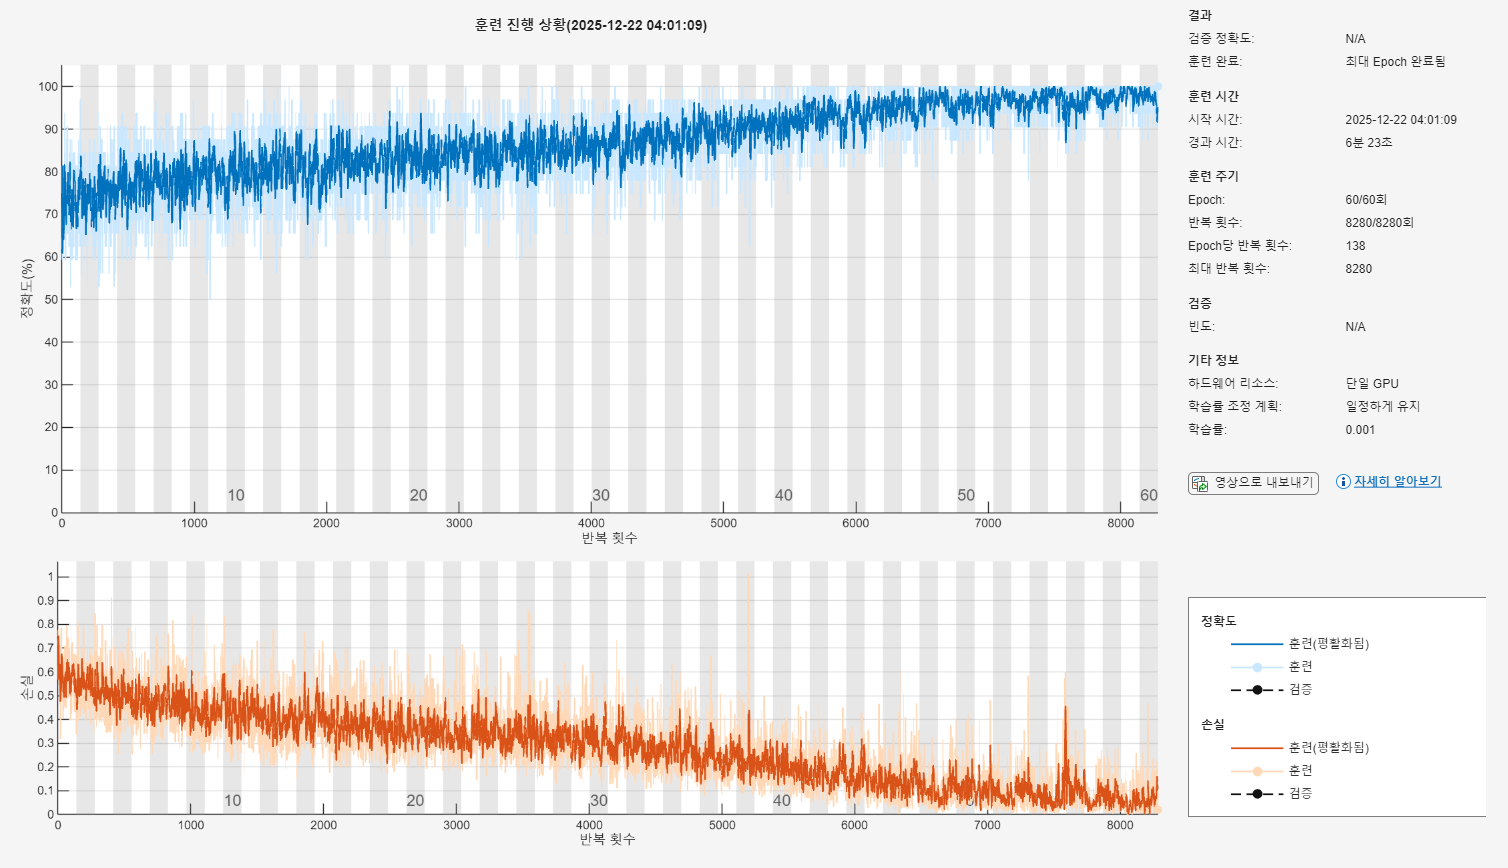


% (필요하면) 길이 강제 통일
targetLen = 311;
for i = 1:numel(Xseq_train)
    L = size(Xseq_train{i},2);
    if L < targetLen
        Xseq_train{i} = padarray(Xseq_train{i}, [0 targetLen-L], 0, 'post');
    elseif L > targetLen
        Xseq_train{i} = Xseq_train{i}(:,1:targetLen);
    end
end
for i = 1:numel(Xseq_test)
    L = size(Xseq_test{i},2);
    if L < targetLen
        Xseq_test{i} = padarray(Xseq_test{i}, [0 targetLen-L], 0, 'post');
    elseif L > targetLen
        Xseq_test{i} = Xseq_test{i}(:,1:targetLen);
    end
end

inputSize = 256;
minLen = targetLen;  % 가장 짧은 길이(여기선 311)

layers = [
    sequenceInputLayer(inputSize,'Name','input','MinLength',minLen)

    convolution1dLayer(5,64,'Padding','same','Name','conv1')
    batchNormalizationLayer('Name','bn1')
    reluLayer('Name','relu1')
    maxPooling1dLayer(2,'Stride',2,'Name','pool1')

    convolution1dLayer(3,128,'Padding','same','Name','conv2')
    batchNormalizationLayer('Name','bn2')
    reluLayer('Name','relu2')
    maxPooling1dLayer(2,'Stride',2,'Name','pool2')

    lstmLayer(64,'OutputMode','last','Name','lstm')

    fullyConnectedLayer(2,'Name','fc')
    softmaxLayer('Name','softmax')
    classificationLayer('Name','output')
];

options = trainingOptions("adam", ...
    "MaxEpochs", 60, ...
    "MiniBatchSize", 32, ...
    "InitialLearnRate", 1e-3, ...
    "Shuffle", "every-epoch", ...
    "Verbose", true, ...
    "Plots", "training-progress");

net_crnn = trainNetwork(Xseq_train, Yseq_train, layers, options);


%%:Step 11-2 평가
YPred = classify(net_crnn, Xseq_test);
confMat = confusionmat(Yseq_test, YPred);

disp("Confusion Matrix [TN FP; FN TP]:");

Confusion Matrix [TN FP; FN TP]:


disp(confMat);

   752    63
   139   156



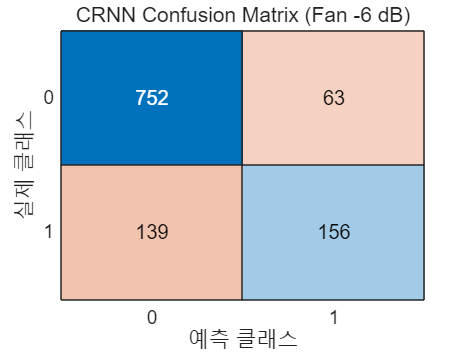

figure;
confusionchart(Yseq_test, YPred);
title("CRNN Confusion Matrix (Fan -6 dB)");

## Step 12: CNN-LSTM 모델 성능 평가

CNN-LSTM으로 학습한 모델을 Accuracy, Precision, Recall, F1-Score 4가지의 지표로 평가하고 ROC Curve 및 AUC를 계산한다.

%% Step 12: CNN-LSTM 학습 후 Accuracy, Precision, Recall, F1-Score 출력
% === 확률 예측 (Softmax 출력)
YPred_prob = predict(net_crnn, Xseq_test);   % [N x 2]
% === confusion matrix (순서 확인 중요)
confMat = confusionmat(Yseq_test, YPred);

% 보통 categorical 순서가 [Negative, Positive]
TN = confMat(1,1);
FP = confMat(1,2);
FN = confMat(2,1);
TP = confMat(2,2);

% === 지표 계산
accuracy  = (TP + TN) / sum(confMat(:));
precision = TP / (TP + FP + eps);
recall    = TP / (TP + FN + eps);
f1_score  = 2 * (precision * recall) / (precision + recall + eps);

% === 출력
fprintf("Accuracy  : %.4f\n", accuracy);

Accuracy  : 0.8180


fprintf("Precision : %.4f\n", precision);

Precision : 0.7123


fprintf("Recall    : %.4f\n", recall);

Recall    : 0.5288


fprintf("F1-score  : %.4f\n", f1_score);

F1-score  : 0.6070


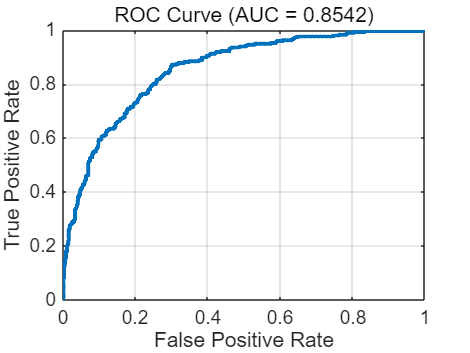

cats = categories(Yseq_test);
Y_true = double(Yseq_test == cats{2});
  
% ↑ 두 번째 category를 Positive로 가정

% === ROC 계산
[fpRate, tpRate, T, AUC] = perfcurve(Y_true, YPred_prob(:,2), 1);

% === ROC Plot
figure;
plot(fpRate, tpRate, 'LineWidth', 2);
grid on;
xlabel('False Positive Rate');
ylabel('True Positive Rate');
title(sprintf('ROC Curve (AUC = %.4f)', AUC));

## Step 13: CNN-LSTM 출력 확률 분포 시각화

CNN 기반 학습과 마찬가지로 이번 모델도 얼마나 모델이 정상과 비정상을 잘 분류하는지를 시각적으로 보여주는 히스토그램을 출력한다.

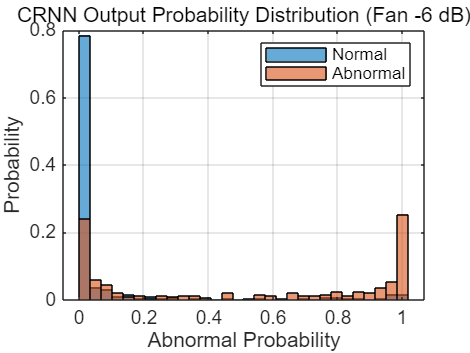

%% Step 13: CNN-LSTM 학습 후 얼마나 Normal/Abnormal 분할이 잘 되는지 플롯
scores = predict(net_crnn, Xseq_test);  
% scores(:,1) = normal 확률
% scores(:,2) = abnormal 확률

figure;
histogram(scores(Y_test==0,2), 30, 'Normalization','probability');
hold on;
histogram(scores(Y_test==1,2), 30, 'Normalization','probability');
hold off;

xlabel("Abnormal Probability");
ylabel("Probability");
legend("Normal","Abnormal");
title("CRNN Output Probability Distribution (Fan -6 dB)");
grid on;

## Step 14: Youden 기반 Threshold 도출

본 단계에서는 CNN-LSTM 모델의 출력 확률을 기반으로 정상 / 비정상 분류에 사용할 최적 임계값을 결정한다. 그래서 TPR(Recall)과 FPR(False Positive Rate)의 균형을 고려하는 Youden Index를 사용한다. Youden Index의 수식은 다음과 같다.

J=TPR-FPR

그래서 위 단계에서는 J의 값이 최대가 되는 Threshold를 자동으로 도출하는 코드 로직이 포함되어  있다.

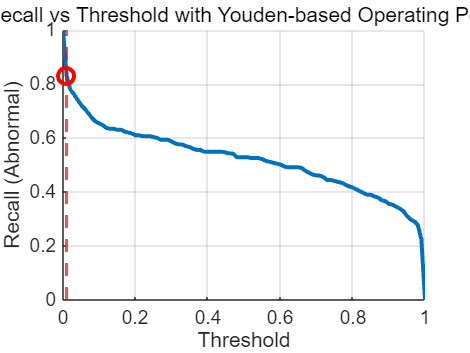

%% Step 14: Youden 기반 Threshold 도출
ths = 0:0.01:1;

TPR = zeros(size(ths));   % Recall
FPR = zeros(size(ths));   % False Positive Rate

for i = 1:length(ths)
    y_tmp = scores(:,2) > ths(i);
    cm = confusionmat(double(Y_test(:)), double(y_tmp(:)));

    % 안전 처리
    if size(cm,1) < 2
        TPR(i) = 0;
        FPR(i) = 0;
        continue;
    end

    TP = cm(2,2); FN = cm(2,1);
    FP = cm(1,2); TN = cm(1,1);

    TPR(i) = TP / (TP + FN + eps);   % Recall
    FPR(i) = FP / (FP + TN + eps);
end

% === Youden 기반 threshold ===
youden = TPR - FPR;
[~, id_thr] = max(youden);
bestThresh = ths(id_thr);

%% === Plot: Recall curve + Youden point ===
figure; hold on;

% Recall vs Threshold 곡선
plot(ths, TPR, 'LineWidth', 2);

% Youden 기준 threshold 점 + 세로선
plot(bestThresh, TPR(id_thr), 'ro', ...
     'MarkerSize', 8, 'LineWidth', 2);
xline(bestThresh, 'r--', 'LineWidth', 1.5);

xlabel("Threshold");
ylabel("Recall (Abnormal)");
title("Recall vs Threshold with Youden-based Operating Point");
grid on;


fprintf("Best Threshold (Youden) = %.2f\n", bestThresh);

Best Threshold (Youden) = 0.01


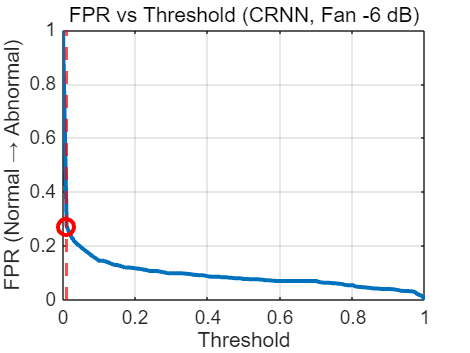

ths = 0:0.01:1;
fpr_list = zeros(size(ths));

for i = 1:length(ths)
    y_tmp = scores(:,2) > ths(i);
    cm = confusionmat(double(Y_test(:)), double(y_tmp(:)));

    TN = cm(1,1);
    FP = cm(1,2);

    fpr_list(i) = FP / (FP + TN + eps);
end

figure;
plot(ths, fpr_list, 'LineWidth', 2); hold on;

% === best threshold 위치 찾기 ===
[~, id_thr] = min(abs(ths - bestThresh));

% === 점 + 세로선 표시 ===
plot(bestThresh, fpr_list(id_thr), 'ro', 'MarkerSize', 8, 'LineWidth', 2);
xline(bestThresh, 'r--', 'LineWidth', 1.5);

xlabel("Threshold");
ylabel("FPR (Normal → Abnormal)");
title("FPR vs Threshold (CRNN, Fan -6 dB)");
grid on;

## Step 15: Youden 기반 Threshold 적용 후 최종 성능 평가

Step 14에서 선정된 최적의 Threshold 값을 넣었을 때 Confusion Matrix, Accuracy, Precision, Recall, F1-Score, AUC를 평가한다.

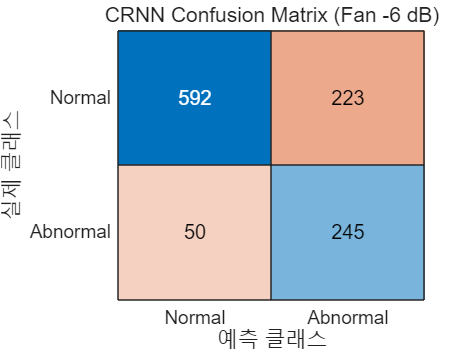

%% Step 15. Threshold로 넣었을 때 모델 성능 최종평가
%% === threshold 기반 재분류 ===
y_opt = scores(:,2) >= bestThresh;   % logical (0/1)

%% === Confusion Matrix (수치 계산용) ===
% --- 수치 계산용 ---
confMat = confusionmat(double(Y_test), double(y_opt));

% --- 시각화용 ---
Y_test_cat = categorical(Y_test, [0 1], {'Normal','Abnormal'});
YPred_cat  = categorical(y_opt,  [0 1], {'Normal','Abnormal'});

figure;
confusionchart(Y_test_cat, YPred_cat);

title("Confusion Matrix (ROC-based Threshold)");

title("CRNN Confusion Matrix (Fan -6 dB)");


TN = confMat(1,1);
FP = confMat(1,2);
FN = confMat(2,1);
TP = confMat(2,2);

%% === 5. 성능 지표 계산 ===
accuracy  = (TP + TN) / sum(confMat(:));
precision = TP / (TP + FP + eps);
recall    = TP / (TP + FN + eps);    % = TPR
f1_score  = 2 * precision * recall / (precision + recall + eps);

fprintf("\n=== Performance Metrics ===\n");


=== Performance Metrics ===


fprintf("Accuracy  : %.4f\n", accuracy);

Accuracy  : 0.7541


fprintf("Precision : %.4f\n", precision);

Precision : 0.5235


fprintf("Recall    : %.4f\n", recall);

Recall    : 0.8305


fprintf("F1-score  : %.4f\n", f1_score);

F1-score  : 0.6422


fprintf("AUC       : %.4f\n", AUC);

AUC       : 0.8542


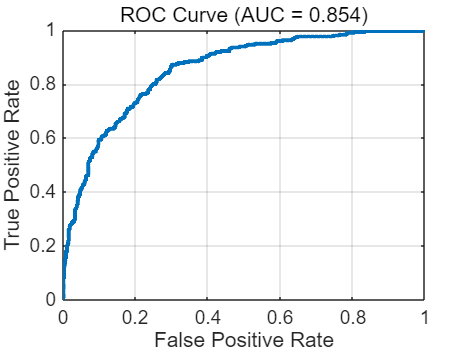


%% === 6. ROC Curve Plot ===
figure;
plot(fpRate, tpRate, 'LineWidth', 2); hold on;
grid on;
xlabel('False Positive Rate');
ylabel('True Positive Rate');
title(sprintf('ROC Curve (AUC = %.3f)', AUC));